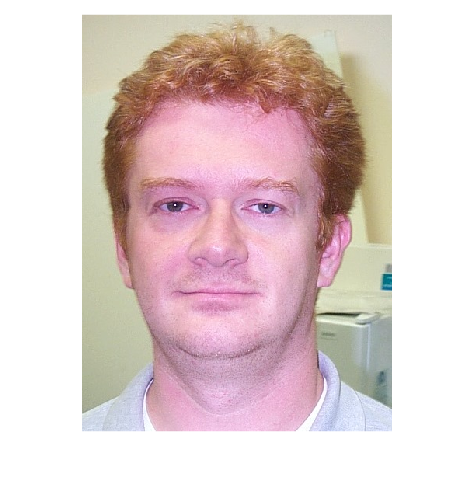

clear
% Problem with: 9

% Read img file
img = imread("../db/DB1/db1_02.jpg");
imshow(img)

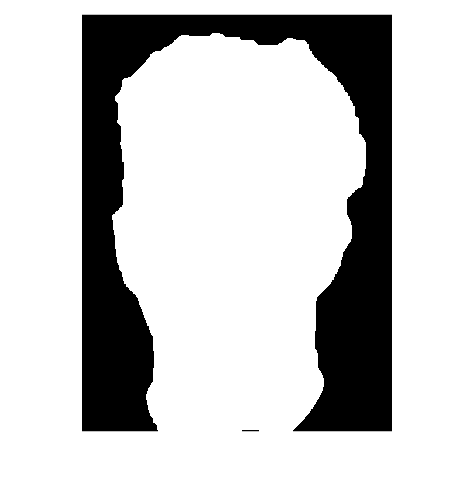


% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

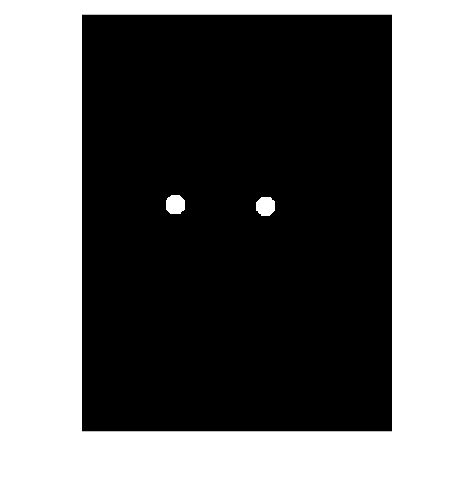


% Find eyes and mouth
eyes = eyemap(img_gw);
eye_mask = eyemask((eyes),face_mask);
imshow(eye_mask)


mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)

[x,y] = mouth_index(mouth_mask)

x = 235.3119

y = 130.5133

[indexX,indexY] = eye_index(eye_mask)

indexX =   120.7609  236.7465


indexY =   245.0000  247.0240



% Replace with actual coordinates
mouth_center = [x, y]; 

% Calculate the distance of each eye center from the mouth center
eye_centers = [indexX(:) + indexY(:)/2, indexY(:)];
distances = sqrt(sum((eye_centers - mouth_center).^2, 2));

% Calculate the distance to the middle
face_mid = [size(img, 2) / 2, size(img, 1) / 2];
eye_distances_to_mid = sqrt((indexX - face_mid(1)).^2 + (indexY - face_mid(2)).^2);

% Sort eyes based on distance to the middle
[sorted_mid_distances, sorted_mid_indices] = sort(eye_distances_to_mid)

sorted_mid_distances =    42.7469   82.0295


sorted_mid_indices =      2     1



% Choose the two closest eyes
closest_mid_eye_indices = sorted_mid_indices(1:2)

closest_mid_eye_indices =      2     1


selected_eyes = [indexX(closest_mid_eye_indices), indexY(closest_mid_eye_indices)];

viscircles([selected_eyes(1),selected_eyes(3)],10)

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


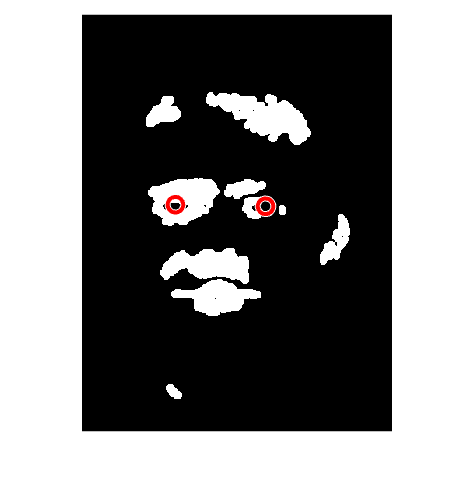

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


viscircles([selected_eyes(2),selected_eyes(4)],10)

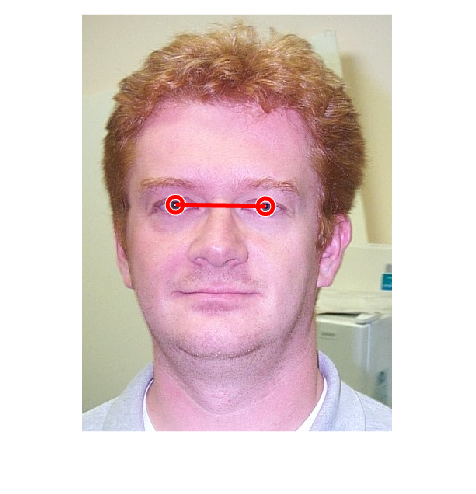


eye1 = [selected_eyes(1),selected_eyes(3)];
eye2 = [selected_eyes(2),selected_eyes(4)];

figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')

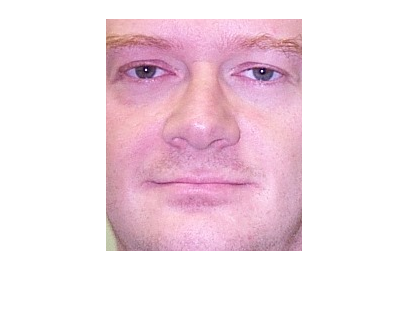


% Define face pixels 
pixels_down_from_eyes = 180; 
pixels_up_from_eyes = 50;    
pixels_sideways_from_eyes = 40; 

% Calculate coordinates for the new triangle
xmin = min([eye1(1), eye2(1)]) - pixels_sideways_from_eyes;
ymin = min([eye1(2), eye2(2)]) - pixels_up_from_eyes;
width = max([eye1(1), eye2(1)]) - xmin + pixels_sideways_from_eyes;
height = max([mouth(2), eye1(2), eye2(2)]) - ymin + pixels_down_from_eyes;

% Image boundries
xmin = max(1, xmin);
ymin = max(1, ymin);
width = min(size(img, 2) - xmin + 1, width);
height = min(size(img, 1) - ymin + 1, height);

% Integer type
xmin = round(xmin);
ymin = round(ymin);
width = round(width);
height = round(height);

% Crop image based on the coordinates
cropped_img = img(ymin:ymin+height-1, xmin:xmin+width-1, :);
figure;
imshow(cropped_img)

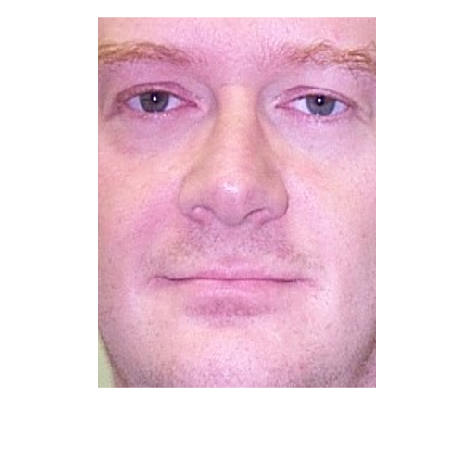


% Desired size
desired_height = 400;
desired_width = 300;

% Change to desired size 
resized_img = imresize(cropped_img, [desired_height, desired_width]);
figure;
imshow(resized_img);